# Example myBspline class code

Fit the function y = x.sin( x ) on the interval [0, 10]. Gaussian noise is added to the data.

## 1. Create training data

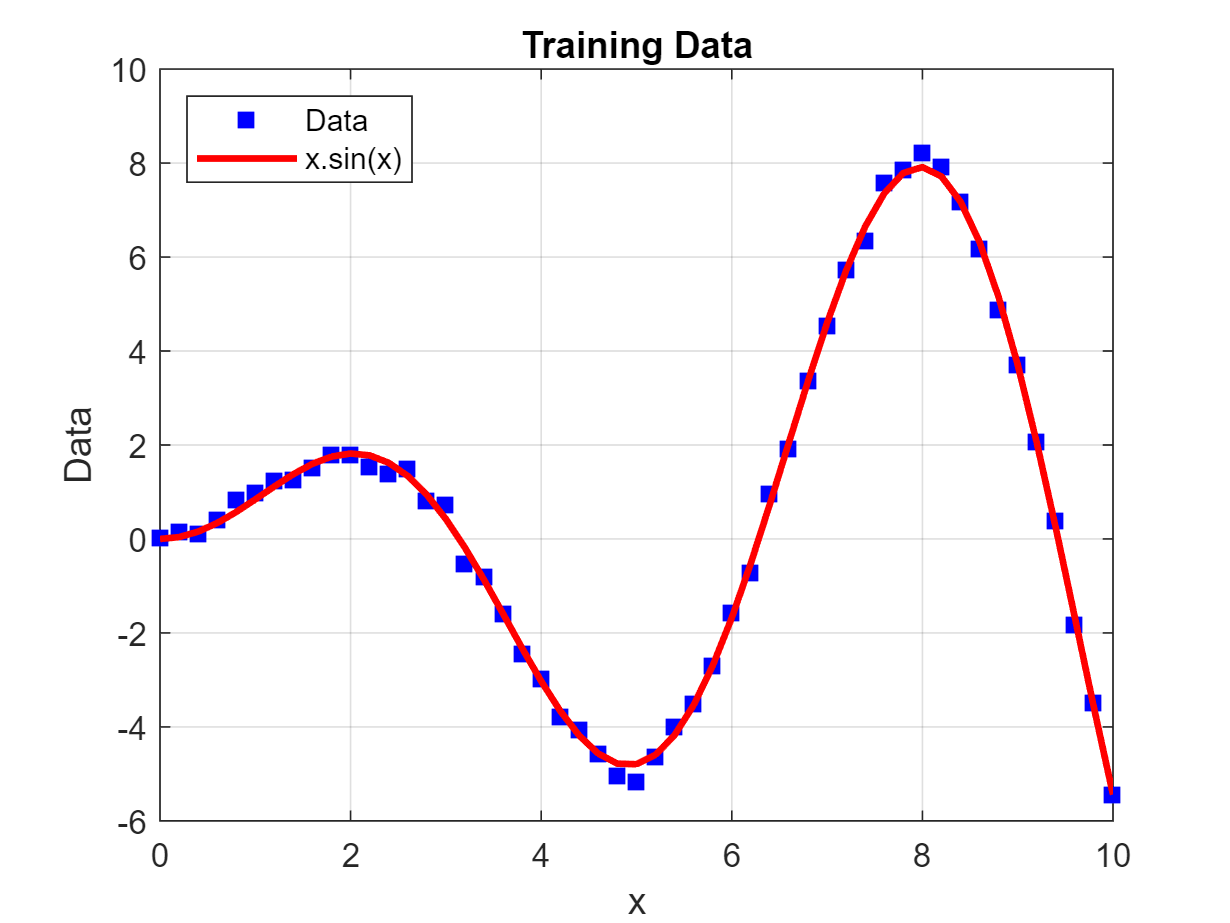

%% Create training data and plot
X = linspace( 0, 10, 51 ).';
Fcn = X.*sin( X );
Y = Fcn + 0.15*randn( 51, 1 );
Ax = axes();
H = plot( X, Y, 'bs', X, Fcn, 'r-');
H( 1 ).MarkerFaceColor = "blue";
H( 2 ).LineWidth = 2;
grid on;
ylabel( "Data");
xlabel( "x" );
title( Ax, "Training Data");
legend( "Data" , "x.sin(x)", 'Location', "northwest")

## 2. Create myBspline objects & Perform Fitting

D = 3;      % Degree of interpolating polynomial
A = 0;                         % Low input data limit for coding
B = 10;                        % High input data limit for coding
for K = 10:-1:1
    S(K) = myBspline( D, K, A, B);
    S(K) = S(K).fit( X, Y );
end

## 3. Perform Fitting